a.) keskiarvosuotimella 

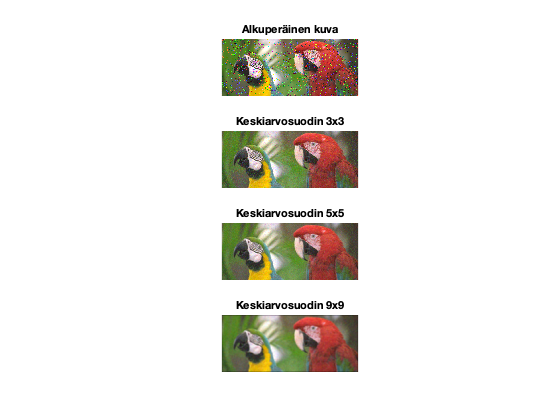

I = imread("rgb1.png");
R = I(:,:,1);
G = I(:,:,2);
B = I(:,:,3);

figure
subplot(4, 1, 1);
imshow(I)
title('Alkuperäinen kuva')

k = 2;
for i=[3 5 9]
    koko = [i,i];
    jakaja = koko(1)*koko(2); 
    h=(1/jakaja)*ones(koko);
    Rfilter = filter2(h, R);
    Gfilter = filter2(h, G);
    Bfilter = filter2(h, B);
    Ifilter = zeros(size(I));
    Ifilter(:,:,1) = Rfilter;
    Ifilter(:,:,2) = Gfilter;
    Ifilter(:,:,3) = Bfilter;
    subplot(4, 1, k)
    imshow(uint8(Ifilter))
    str =  ("Keskiarvosuodin " + i + "x" + i);
    title(str)
    k = k + 1;
end

b.)

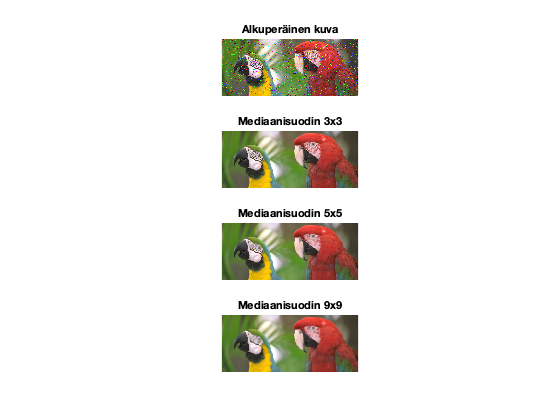

figure
subplot(4, 1, 1);
imshow(I)
title('Alkuperäinen kuva')

k = 2;
for i=[3 5 9]
    Rfilter = medfilt2(R, [i i]);
    Gfilter = medfilt2(G, [i i]);
    Bfilter = medfilt2(B, [i i]);
    Ifilter = zeros(size(I));
    Ifilter(:,:,1) = Rfilter;
    Ifilter(:,:,2) = Gfilter;
    Ifilter(:,:,3) = Bfilter;
    subplot(4, 1, k)
    imshow(uint8(Ifilter))
    str =  ("Mediaanisuodin " + i + "x" + i);
    title(str)
    k = k + 1;
end

Mediaanisuotimen tulokset paremmat kuin keskiarvosuotimella. Keskiarvosuotimella kohina pysyi paremmin ja kuva nopeasti suotimen kokoa kasvattamalla sumeni. Mediaanisuotimessa koko 3x3 oli parhain ja 5x5 suotimen jälkeen kuva alkoi sumentumaan.

Keskiarvosuodin sumentaa kuvaa enemmän, koska se on lineaarinen alipäästösuodin ja se ottaa huomioon kaikki naapuruston pisteet samalla tavalla. Mediaanisuodin on epälineaarinen ja pitää yksityiskohdat paremmin (kuva ei sumennu yhtä helposti).